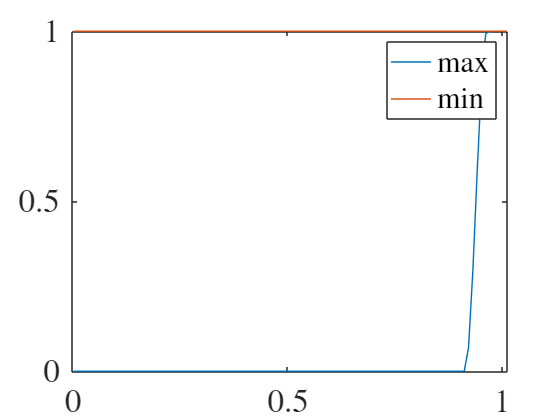

parameters
omega = [0.001:0.01:omega_rated]';

sigma_min = sigma(generator.omega1_min, generator.omega2_min, omega);
sigma_max = sigma(generator.omega1_max, generator.omega2_max, omega);
Qmin = min(sigma_min.*generator.K_opt.*omega.^2, generator.K_opt*generator.omega1_max^2);
Qmax = max((1 - sigma_max)*generator.K_opt.*omega.^2 + sigma_max*generator.torque_full, generator.K_opt*generator.omega2_min.^2);

figure()
plot(omega, sigma_max, 'DisplayName', 'max');
hold on
plot(omega, sigma_min, 'DisplayName', 'min');
legend()

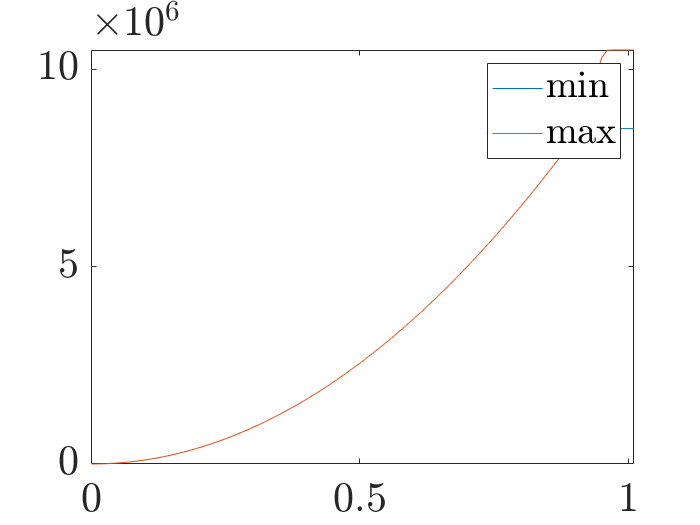


figure()
plot(omega, Qmin, 'DisplayName', 'min');
hold on
plot(omega, Qmax, 'DisplayName', 'max');
legend()

function y = sigma(x0, x1, x)
  a = [2 -3*(x0 + x1) 6*x1*x0 (x0 - 3*x1)*x0^2]/(x0 - x1)^3;  % poly coeff.

  len = length(x);
  y = zeros(len, 1);
  for i=1:len
    if x(i) < x0
      y(i) = 0;
    elseif x0 <= x(i) && x(i) <= x1
      y(i) = polyval(a, x(i));  
    else 
      y(i) = 1;
    end
  end
end
